# Sampled Average Estimator: Unbiasedness and Mean Square Convergence 

## Motivating Example

Suppose to acquire measurements of the internal temperature of a Lithium-ion battery, using a thermocouple or a resistance temperature detector (RTD), with the aim to monitor the safety of the cell and to early detect  the thermal runaway of the cell itself.

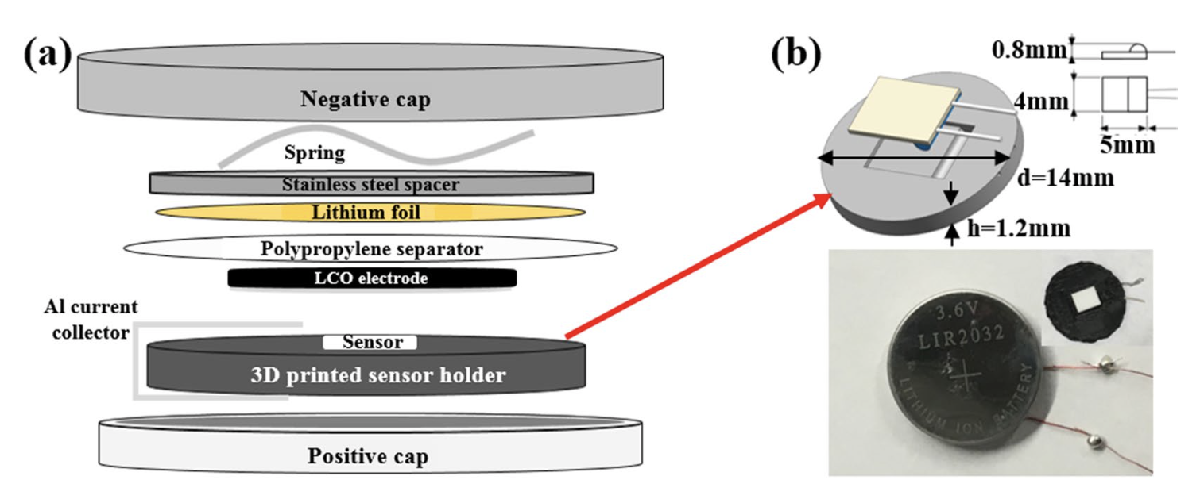

Figure 1: Example of an RTD sensor embedded in a CR2032 cell (from[1])

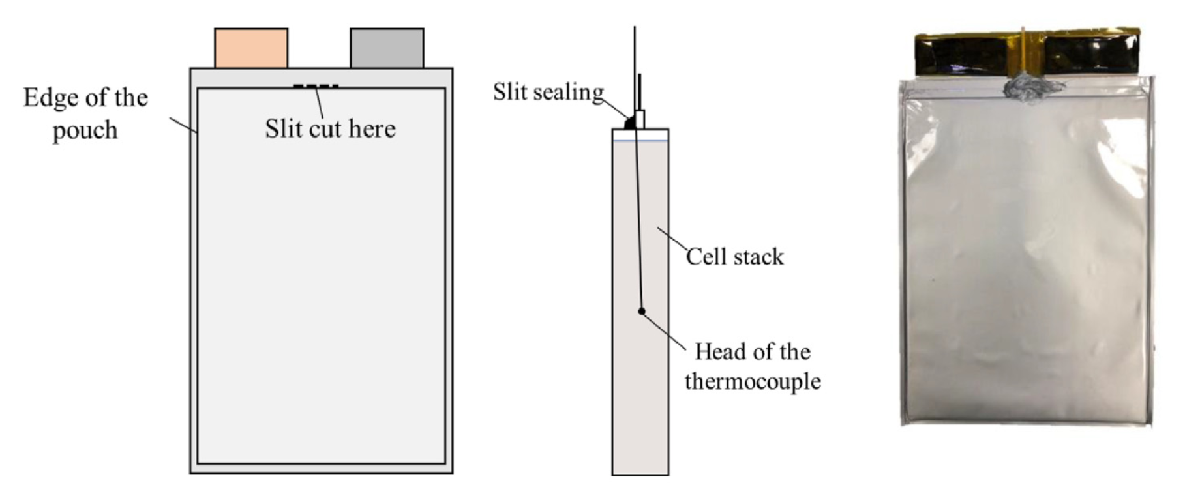

Figure 2: Example of a thermocouple installed in a Lithium-ion pouch cell (from [2]).

Let us assume that the battery temperature is constant, and perform $N$ measurements $\, d(1)\,,\; d(2)\,,\; \ldots\,,\; d(N) \,$such that 


$$\text{E} \left[ d(i) \right] = \vartheta^{\circ}\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


where $\vartheta^{\circ}\,$is the unknow temperature value of the cell.

Assume that data are mutually uncorrelated, that is

			
$$\text{E} \left\{ \left[  d(i) - \vartheta^{\circ} \right] \, \left[ d(j) - \vartheta^{\circ} \right]\right\} = 0 \;, \quad \forall i \ne j$$


How to estimate the cell temperature, given the data $\, d(1)\,,\; d(2)\,,\; \ldots\,,\; d(N) \,$?


$$\hat{\vartheta}_{N}= \displaystyle f\big( \, d(1)\,,\; d(2)\,,\; \ldots\,,\; d(N) \,\big)$$


What about the features of the estimator?

## The Sampled Average Estimator: the Features				

Given $N$ random variables $\, d(1)\,,\; d(2)\,,\; \ldots\,,\; d(N) \,$such that


$$\text{E} \left[ d(i) \right] = \vartheta^{\circ}\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  d(i) - \vartheta^{\circ} \right] \, \left[ d(j) - \vartheta^{\circ} \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\vartheta}_{N}= \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} d(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\vartheta}_{N}\right] = \vartheta^{\circ}$$
			

Moreover, the variance of the estimate is


$$\text{var} \left( \hat{\vartheta}_{N} \right) = \displaystyle \frac{1}{N^2} \sum_{i=1}^{N}\,\text{var}\big(d(i)\big)$$


If $$\text{var} \left[ d(i) \right] \le \bar{\sigma}\, , \; i =1\,,\; 2\,,\; \ldots \,,\; N$  	 $then 


$$\lim_{N \to \infty} \text{var} \left( \hat{\vartheta}_{N} \right) \le \lim_{N \to \infty} \frac{\bar{\sigma}}{N}=0$$


Thus, the **estimator converges in quadratic mean**. This implies also that the $\hat \vartheta_N$ is a **consistent estimator** of the mean value.

#### Hands-On: the Consistency of the Sample Mean

In this previous section, it was shown that the sample mean $\hat \vartheta_N$ is a consistent estimator. This is illustrated in this exercise. The sample mean $\hat \vartheta_N$ of $N$ uncorrelated samples $\{d(i)\}, i=1,\ldots,N$ is calculated from $N_R=1000$ repeated simulations for $N=10,10^2,10^3,10^4, 10^5, 10^6$ and the results are plotted as a function of $N$in the first figure. The pdf of $\hat \vartheta_N$is shown in the second plot, for the different values of $N$. The r.v. $d(i)\;i=1\,,2\,,\ldots N$ have mean value $\vartheta^{\circ}=0$ and variance $\sigma^2_{d(i)} =1\; \;i=1\,,2\,,\ldots N$.

The following observations can be made:

- On the first plot, it can seen that the estimates $\hat \vartheta_N$ are scattered around zero.

- The scattering reduces for growing values of $N$.

- This shows that the pdf of $\hat \vartheta_N$ contracts around its mean value $\vartheta^{\circ}=0$. This is clearly visible in the bottom plot where the pdf $f_{\hat \vartheta_N}$ is shown for the different values of $N$.

- For a fixed interval $[-\epsilon,\epsilon]$ we have that the probability that an estimate $\hat \vartheta_N$ will be outside this interval drops to zero with growing $N$, due to the vanisnhing of the variance: remember the **Tchebicev inequality** 

clear 
close all
clc

let's create the data sequences

NAll=logspace(1, 5, 5);  % number of measurements in a single simulation: log-spaced data

NR = 1000       ;        % number of repeated simulations

n = length(NAll);        % how many dataset?

 


for kN = n:-1:1        % loop over the data lengths
    N = NAll(kN);
    for kR = NR:-1:1   % loop over the repeated simulations
      x = randn(N,1);  % generate the random variable: N gaussian uncorrelated r.v.
                       % each of them with E(x) = 0 and var(x) = 1

      xMeanAll(kR,kN) = mean(x);  % estimate the mean value using the sample mean
    end
end

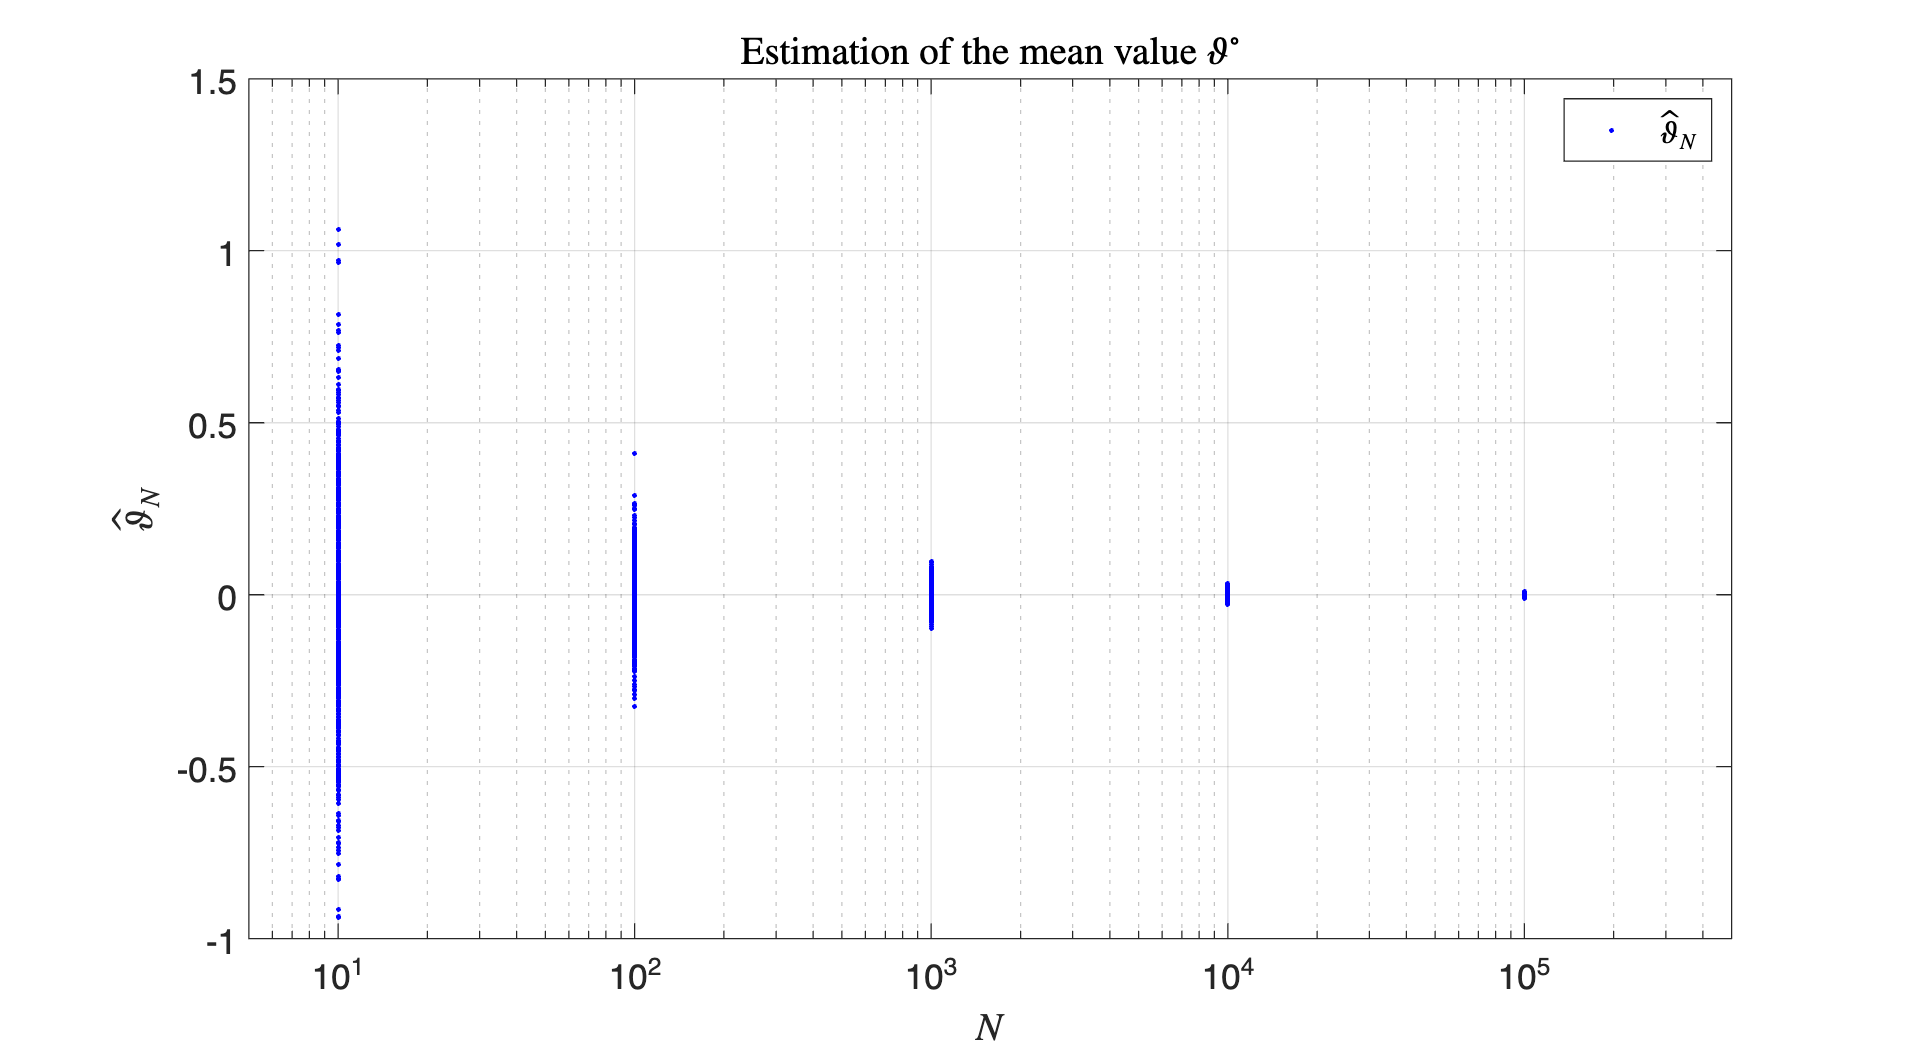

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
% --- Let's show the estimator behaviour ---
semilogx(NAll,(xMeanAll),'.b'); % a logarithmic (base 10) scale is used for the X-axis
xlim([5,5e5]); % setting the limits of the plot on the X-axis
xlabel('$N$','interpreter','latex');
ylabel('$\hat{\vartheta}_N$','interpreter','latex');
legend('$\hat{\vartheta}_N$','interpreter','latex');
title('Estimation of the mean value $\vartheta^{\circ}$','interpreter','latex');
set(gca, 'Fontsize', 14); % choosing a larger font size
grid on % and enabling the grid 

Note as when the number $N$ of data increases, the scattering of the estimates $\hat{\vartheta}_{N}$ reduces: for each value of $N$there are always $N_R$ evaluations of the sample average.

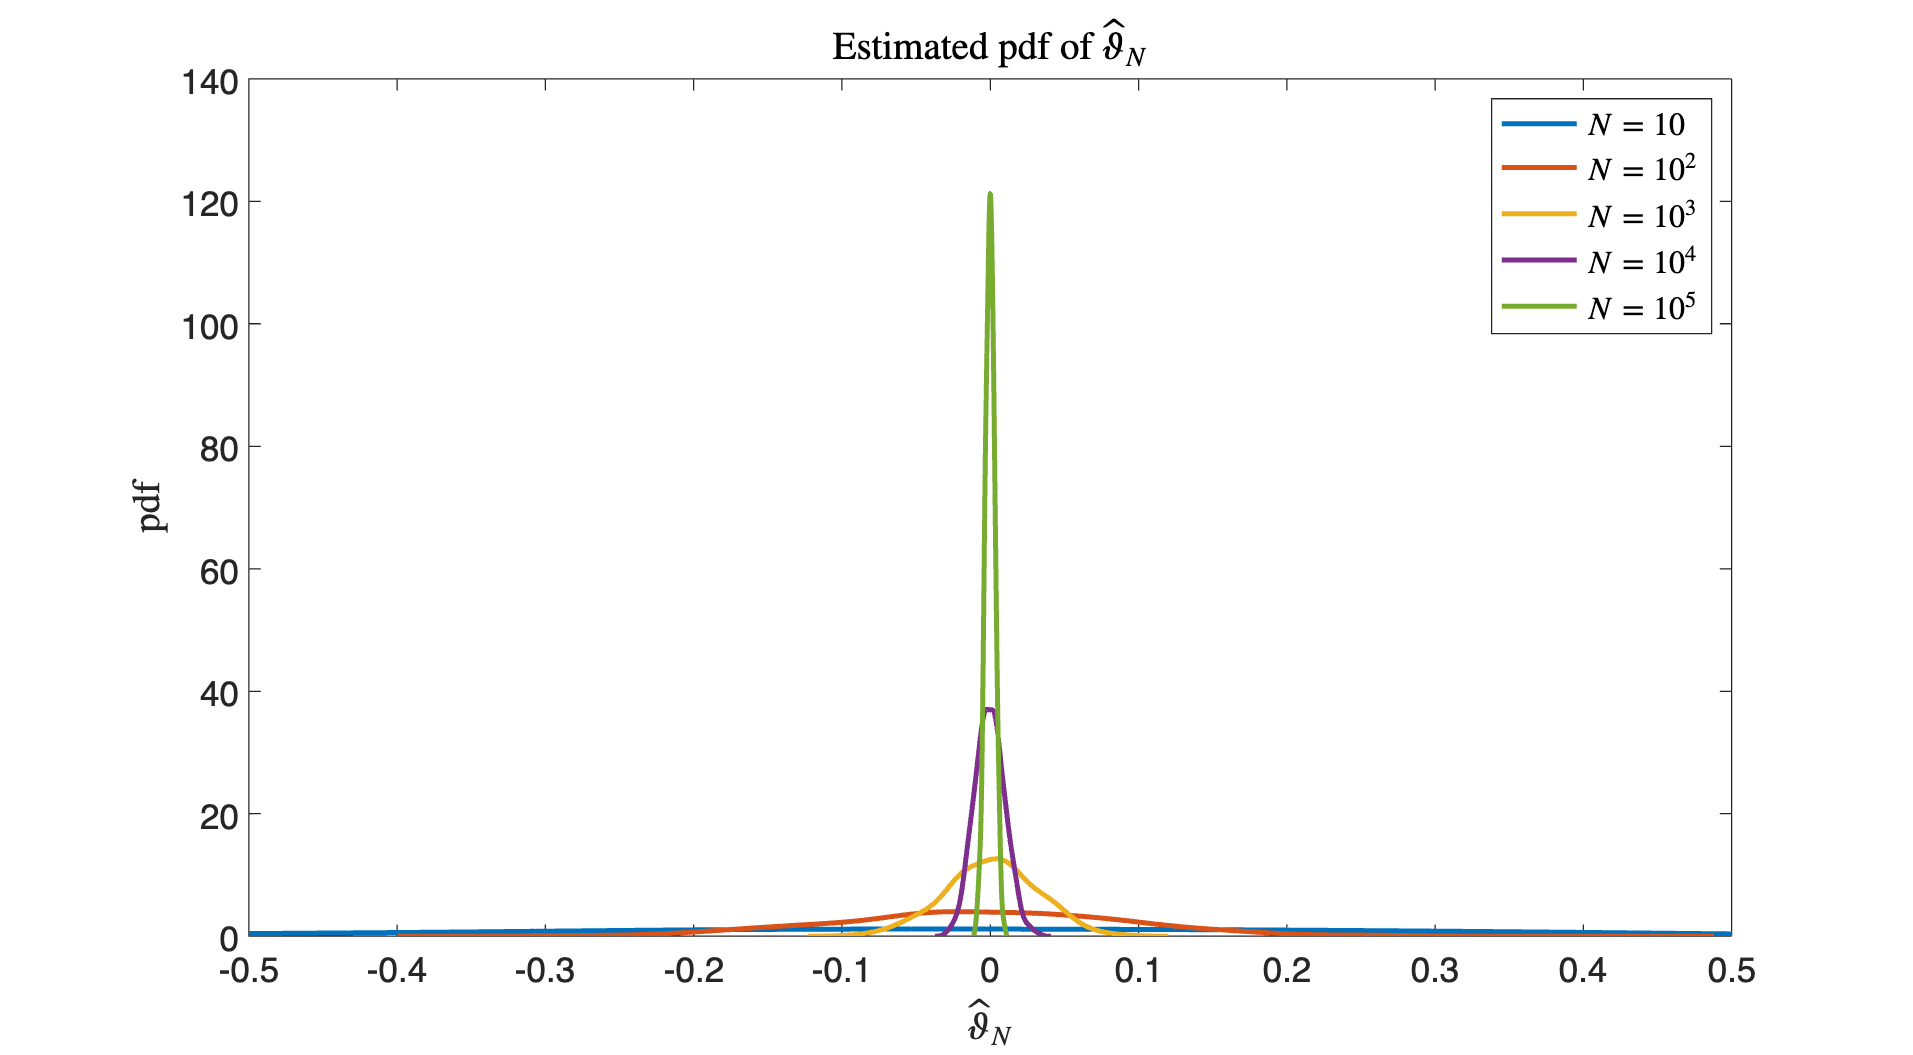

% evaluate the pdf of the sample means
for k = numel(NAll):-1:1
    [Xpdf(:,k),Xc(:,k)] = ksdensity(xMeanAll(:,k)); % let's evaluate the pdf
                                                    % please check: 
                                                    %   help ksdensity
end
% 
figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
% plot the pdf of the sample means
plot(Xc,Xpdf,'linewidth',2);
xlim([-0.5 0.5]); 
xlabel('$\hat{\vartheta}_N$','interpreter','latex');
ylabel('pdf','interpreter','latex');
legend('$N=10$','$N=10^2$','$N=10^3$','$N=10^4$','$N=10^5$',...
         'interpreter','latex');
title('Estimated pdf of $\hat{\vartheta}_N$','interpreter','latex');
set(gca, 'Fontsize', 14); % choosing a larger font size

Note: the pdf contracts around the mean value $\vartheta^{\circ}$ when $N$ increases.

## References

For details on the sampled-average estimator features refer to:

    Bittanti S., *Model Identification and Data Analysis, *Wiley, 2019

    Ljung L., *System Identification: Theory for the User*. 2nd Edition, Prentice Hall PTR, 1999

For the initial examples images refer to:

[1] Li, B., Parekh, M.H., Adams, R.A. *et al.* Lithium-ion Battery Thermal Safety by Early Internal Detection, Prediction and Prevention. *Sci Rep* **9**, 13255 (2019). 

[2] Chengshan Xu, Fangshu Zhang, Xuning Feng, Fachao Jiang, Dongsheng Ren, Languang Lu, Yang Yang, Guanwei Liu, Xuebing Han, Benedikt Friess, Minggao Ouyang, *Experimental study on thermal runaway propagation of lithium-ion battery modules with different parallel-series hybrid connections*, Journal of Cleaner Production, Volume 284, 2021